# Parameter Estimation for Discrete-SIR models

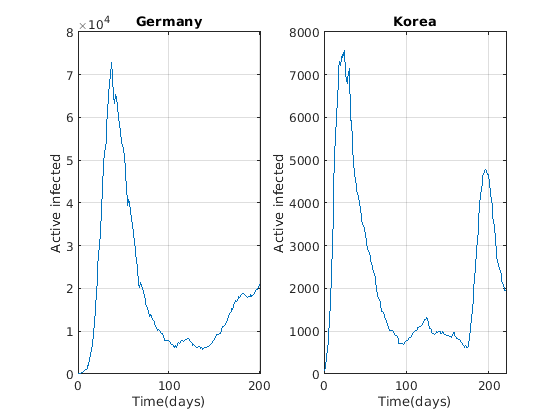

Localities = ["Germany", "Korea"];

time = {40:140; 30:130};
% time = {40:240; 30:250};
Population = [8.3e7; 5.1e7];
ydata = cell(length(Localities),1);

for i = 1: length(Localities)
    load('Data/' + Localities(i) + '.mat')
    ydata_aux = [Cases - Recovered - Death; Recovered];
    ydata{i} = ydata_aux(:,time{i});
end

figure
subplot(1,2,1)
plot(ydata{1}(1,:))
grid on
ylabel("Active infected")
xlabel("Time(days)")
title(Localities{1})

subplot(1,2,2)
plot(ydata{2}(1,:))
grid on
ylabel("Active infected")
xlabel("Time(days)")
title(Localities{2})

close all
VarNames = {'S', 'I', 'R','I_c'};
OutNames = {'S', 'I', 'R', 'R_{c}','I_c', 'N'};
ParNames = {'\gamma','\mu','z', '\nu'};

FullNames = [VarNames,ParNames];
ModelNames = ["Simple", "Complex", "Classic"];

T_save = cell(length(Localities), length(ModelNames));  

for k = 1:length(Localities)
% for k=1:2
    RealData = ydata{k};  
    Range1 = [
        0 Population(k); 
        RealData(1,1) RealData(1,1);
        0 20000;
        RealData(1,1) RealData(1,1);
        ];
    
    Range2 = [
            0 1;        % gamma   
            0 0.01;        % mu
            0 30;        % z
            0 1000       %nu
            ];
    
    RangeT = [Range1; Range2];
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    N = 1000;
    extra = struct();
    Parameters = [];
    Res = [];
    
    for i = 1:3
        
        extra.Prob = i;
        %%Prob = 1 -> psi(simple)
        %%Prob = 2 -> phi(complex)
        %%Prob = 3 -> classical
        
        [T,~] = gsua_dataprep("CHIMERA_SIR", RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);
        outs = [2]; 
        T.Properties.CustomProperties.output = outs;
        
        if i == 3
            T.Range(end-1,:) = [0 1];
        end
        
        if i == 2
            T.Range(end,:) = [0 3000];
        end
        
        T_save{k, i} = T;
%         
%         Solver = 'lsqc';
%            
%         Opt = optimoptions('lsqcurvefit', 'UseParallel', false,'MaxFunctionEvaluations', 30000, ...
%             'MaxIterations', 3000, 'Display','off');
%         
%         parfor j = 1:N
%             [T_aux, Res_aux] = gsua_pe(T, xdata, RealData(1,:),...
%                 'solver', Solver,'N', 1,'opt', Opt,'save', false);
%             Parameters(:,j) = T_aux.Estlsqc;
%             Res(j) = Res_aux;
%         end
%         
%         [Res, idx] = sort(Res);
%         Parameters = Parameters(:,idx);     
%         T_save{i}.Nominal = Parameters(:,1);
%         save("Results/Estimations_Extra_Disc_" + Localities(k) + "_Aleph_" + ModelNames(i), "Res",  "Parameters")
%         
%         figure
%         gsua_eval(Parameters(:,1), T_save{k, i}, xdata, RealData(1,:));
%         suptitle(ModelNames(i) + " residual: " + Res(1) + " Locality:" + Localities{k})
    end
end

Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function
Setting environment to work with user-defined function


[T,~] = gsua_dataprep("CHIMERA_SIR", RangeT, 'domain', Domain, 'names',...
            FullNames, 'out_names', OutNames,'opt', extra);

Setting environment to work with user-defined function


outs = 2; 
T.Properties.CustomProperties.output = outs;
T_aux = [];
for k = 1:length(Localities)
%     Localities(k)
    for i = 1:3
    load("Results/Estimations_Extra_Disc_" + Localities(k) + "_Aleph_" + ModelNames(i));
    T_aux = [T_aux, Parameters(:,1)];
%     ModelNames(i)
    end
end
T.Params = T_aux;
T

T = 6×3 table
                 Range        Nominal        Params   
              ____________    ________    ____________

    S         0    5.1e+07    2.55e+07    [1×6 double]
    R         0      20000       10000    [1×6 double]
    \gamma    0          1         0.5    [1×6 double]
    \mu       0       0.01       0.005    [1×6 double]
    z         0         30          15    [1×6 double]
    \nu       0       1000         500    [1×6 double]


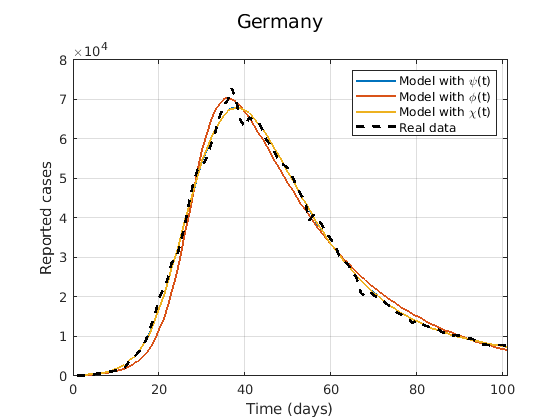

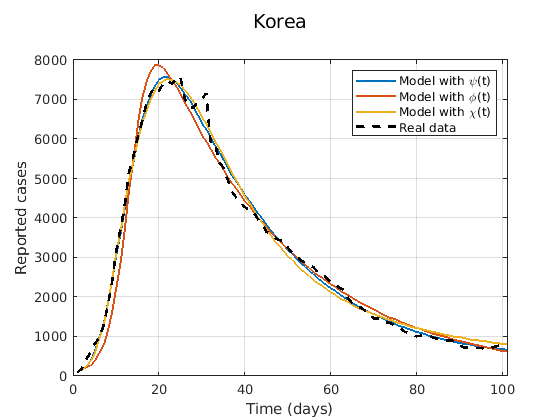

close all
IdxSims = [];

FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/";

Titles = ["Model with \psi(t)"; 
    "Model with \phi(t)";
    "Model with \chi(t)";
    "Real data"];

for k = 1:length(Localities)
    
    A = rand(3,3);
    cm = colormap(lines(size(A,1)));
    
    counter = 1;
    RealData = ydata{k};    
    figure
    
    D = length(RealData(1,:));
    Domain = [0 D-1];
    xdata = 0:D-1;
    
    for i = 1:3
        load("Results/Estimations_Extra_Disc_" + Localities(k) + "_Aleph_" + ModelNames(i))
        N = size(Res, 2);
        T_save{k,i}.Properties.CustomProperties.output = 2;
        ysim = zeros(N, 1, D);
        for j = 1:N
            ysim(j,:,:) = gsua_deval(Parameters(:,j)', T_save{k,i}, xdata);
%             Res(j) = immse(squeeze(ysim(j,:,:)), RealData(1,:)');
    %         Res(i) = norm(squeeze(ysim(i,:,:)) - ydata(1:2,:));
        end
        
        [~, Idx] = sort(Res);
        IdxSims(k) = Idx(1);
        
        for j = 1:1        
%             subplot(3,1,counter)
            plot(squeeze(ysim(IdxSims(k), j, :))', 'Color', cm(i,:),'LineWidth',1.5); 
            hold on
            grid on
%             title(Titles(counter))
            counter = counter +1;
            xlim([0 length(RealData)]);
        end
        suptitle(Localities(k))
    end
    xlabel("Time (days)")
    ylabel("Reported cases")
    hold on
    plot(RealData(j,:)','--k','LineWidth',2)
    legend(Titles)    
    savefig(FolderFigures + "Fit_EXTRA_" + Localities(k) + "Discrete.fig")
    saveas(gcf,FolderFigures + "Fit_EXTRA_" + Localities(k) + "Discrete.png")
end

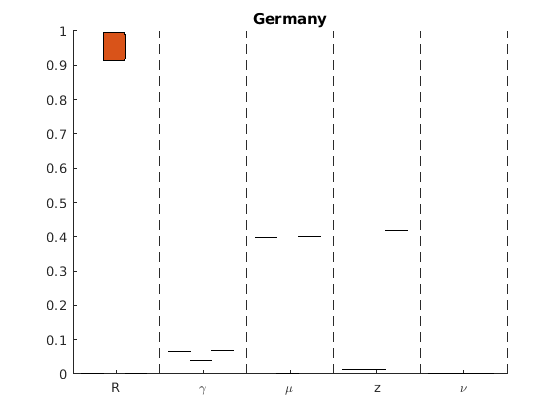

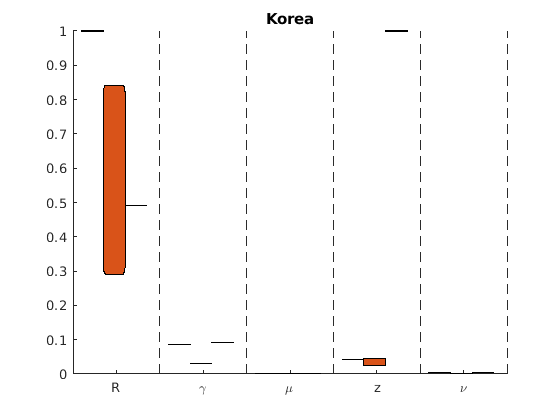

close all
for k = 1 :2
figure
FolderFigures = "/home/curie/MATLAB-Drive/CHIMERITApaper/Figures/";
A = rand(3,3);
cm = colormap(lines(size(A,1)));
x=[];
mx=[];
P=[];

for i=1:3
    load("Results/Estimations_Extra_Disc_" + Localities(k) + "_Aleph_" + ModelNames(i))
    P = (Parameters-T_save{k, i}.Range(:,1))./(T_save{k, i}.Range(:,2)-T_save{k, i}.Range(:,1));
    
    for j = 1:6
        Pq = rmoutliers(P(j,:),'percentiles', [10 90]);
        Pq = quantile(Pq',[0.25 0.75])';
%         Pq = [min(Pq) max(Pq)]';
        rectangle('Position',[j+0.25*(i-1) Pq(1) 1/4 Pq(2)-Pq(1)],'FaceColor',[cm(i,:),0.5],'Curvature',0.2)
        hold on
        text(0,j+0.75,string(T_save{k, i}.Properties.RowNames(j)))
        x(j) = j+0.9;
        xline(x(j),'--')
        if j>1
            mx(j) = x(j-1)+(x(j)-x(j-1))/2;
        else
            mx(j) = (x(j)+1)/2;
        end        
    end
end

    xlim([min(x) max(x)])
    xticks(mx)
    set(gca,'XTickLabel',T_save{k, i}.Properties.RowNames,'TickLabelInterpreter', 'tex')
    title(Localities(k))    
    savefig(FolderFigures + "PIA_EXTRA_" + Localities(k) + "Discrete.fig")
    saveas(gcf,FolderFigures + "PIA_EXTRA_" + Localities(k) + "Discrete.png")
end

**Sensitivity analisys for estimation intervals**

N = 10000;
M = gsua_dmatrix(T, N, 'Method', 'Sobol');

T_save{1} = gsua_sa(M,T_save{1});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:3:33
Remaining time (h:m:s): 0:2:58
Elapsed time (h:m:s): 0:0:35
Estimated stop time (h:m:s): 15:43:27
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:3:34
Remaining time (h:m:s): 0:2:22
Elapsed time (h:m:s): 0:1:11
Estimated stop time (h:m:s): 15:43:28
Number of simulations: 30000
Finding the deepest curve...


sum(T_save{1}.Si)/sum(abs(T_save{1}.Si))
figure
gsua_plot('Pie',T_save{1},T_save{1}.STi)
figure
gsua_plot('Bar',T_save{1},T_save{1}.STi)
T_save{2} = gsua_sa(M,T_save{2});
sum(T_save{2}.Si)/sum(abs(T_save{2}.Si))
figure
gsua_plot('Pie',T_save{2},T_save{2}.STi)
figure
gsua_plot('Bar',T_save{2},T_save{2}.STi)

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 19:1:48
Number of simulations: 1000


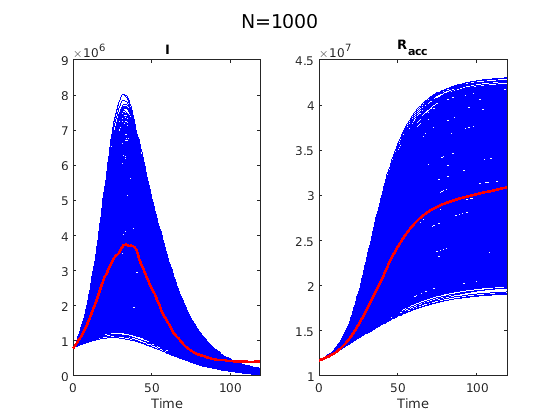

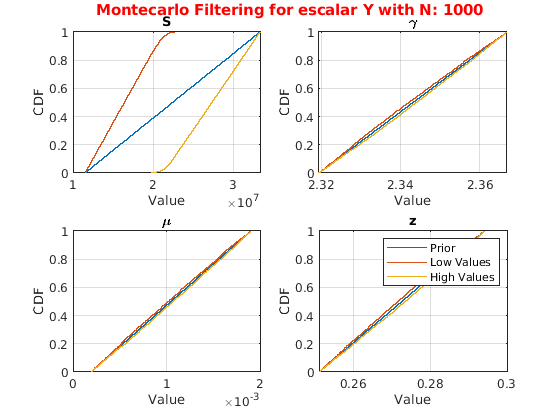

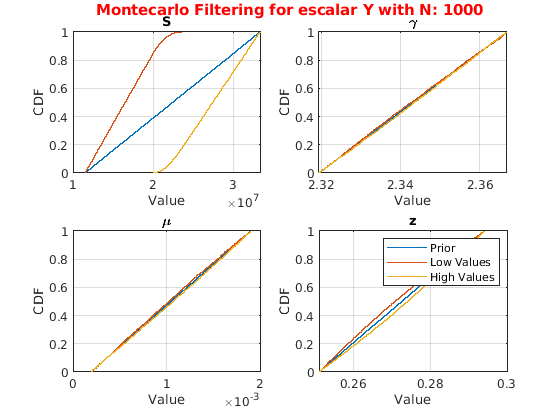

N = 1000;
M = gsua_dmatrix(T_ia{1}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{1},'xdata', xdata, 'ynom', ydata, 'parallel', false);

N = 10000;

M = gsua_dmatrix(T_ia{1}, N, 'Method', 'Sobol');
T_ia{1} = gsua_sa(M,T_ia{1});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:0:52
Remaining time (h:m:s): 0:0:43
Elapsed time (h:m:s): 0:0:8
Estimated stop time (h:m:s): 9:45:15
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:0:49
Remaining time (h:m:s): 0:0:32
Elapsed time (h:m:s): 0:0:16
Estimated stop time (h:m:s): 9:45:12
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:26:28
Remaining time (h:m:s): 0:13:14
Elapsed time (h:m:s): 0:13:14
Estimated stop time (h:m:s): 10:10:51
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 0:20:3
Remaining time (h:m:s): 0:6:41
Elapsed time (h:m:s): 0:13:22
Estimated stop time (h:m:s): 10:4:26
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:16:12
Remaining time (h:m:s): 0:2:42
Elapsed time (h:m:s): 0:13:30
Estimated stop time (h:m:s): 10:0:35
Number of simulations: 30000
Progress: 100%
Estimated proces

sum(T_ia{1}.Si)/sum(abs(T_ia{1}.Si))

ans = 1

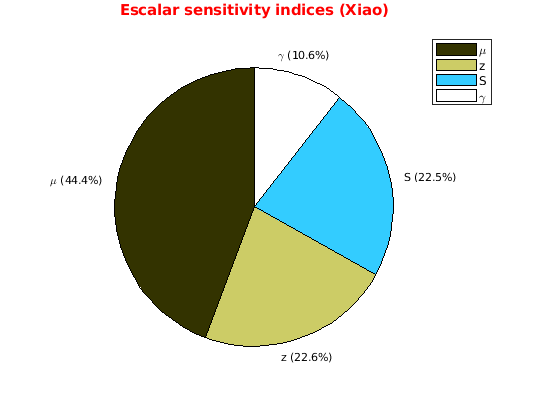

figure
gsua_plot('Pie',T_ia{1},T_ia{1}.STi)

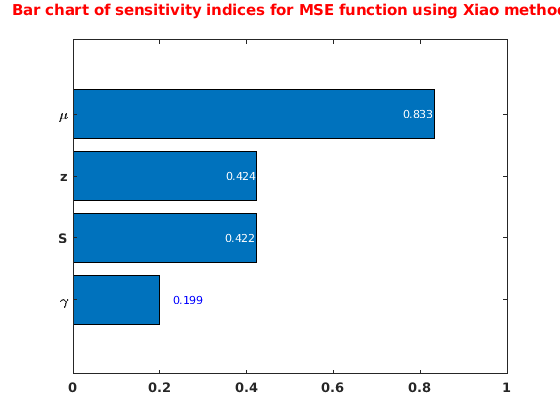

figure
gsua_plot('Bar',T_ia{1},T_ia{1}.STi)

M = gsua_dmatrix(T_ia{2}, N, 'Method', 'Sobol');
T_ia{2} = gsua_sa(M,T_ia{2});

Current outputs:1  2  3
Progress: 17%
Estimated processing time (h:m:s): 0:1:51
Remaining time (h:m:s): 0:1:32
Elapsed time (h:m:s): 0:0:18
Estimated stop time (h:m:s): 9:59:54
Number of simulations: 30000
Progress: 34%
Estimated processing time (h:m:s): 0:1:52
Remaining time (h:m:s): 0:1:15
Elapsed time (h:m:s): 0:0:37
Estimated stop time (h:m:s): 9:59:55
Number of simulations: 30000
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 1:31:48
Remaining time (h:m:s): 0:45:54
Elapsed time (h:m:s): 0:45:54
Estimated stop time (h:m:s): 11:29:51
Number of simulations: 30000
Progress: 67%
Estimated processing time (h:m:s): 1:9:25
Remaining time (h:m:s): 0:23:8
Elapsed time (h:m:s): 0:46:17
Estimated stop time (h:m:s): 11:7:28
Number of simulations: 30000
Progress: 84%
Estimated processing time (h:m:s): 0:56:0
Remaining time (h:m:s): 0:9:20
Elapsed time (h:m:s): 0:46:40
Estimated stop time (h:m:s): 10:54:3
Number of simulations: 30000
Progress: 100%
Estimated proces

sum(T_ia{2}.Si)/sum(abs(T_ia{2}.Si))

ans = 1

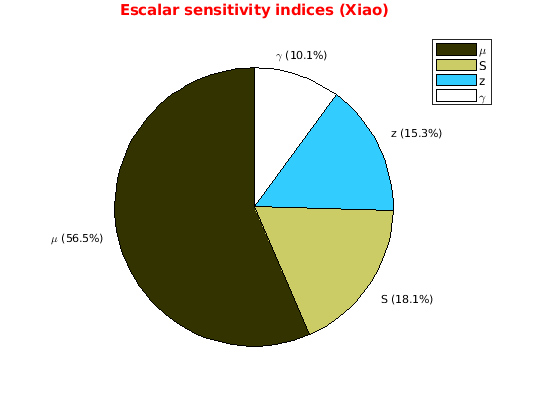

figure
gsua_plot('Pie',T_ia{2},T_ia{2}.STi)

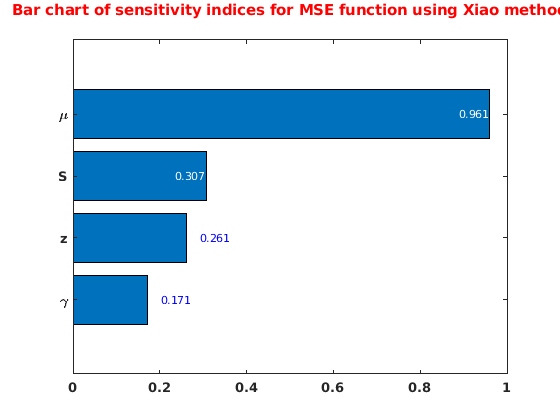

figure
gsua_plot('Bar',T_ia{2},T_ia{2}.STi)

M = gsua_dmatrix(T_ia{3}, N, 'Method', 'Sobol');
T_ia{3} = gsua_sa(M,T_ia{3});

Current outputs:2  3
Progress: 17%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:25:3
Number of simulations: 30
Progress: 34%
Estimated processing time (h:m:s): 0:0:1
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 13:25:3
Number of simulations: 30
Finding the deepest curve...
Progress: 50%
Estimated processing time (h:m:s): 0:0:3
Remaining time (h:m:s): 0:0:1
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:25:4
Number of simulations: 30
Progress: 67%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:25:4
Number of simulations: 30
Progress: 84%
Estimated processing time (h:m:s): 0:0:2
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:1
Estimated stop time (h:m:s): 13:25:4
Number of simulations: 30
Progress: 100%
Estimated processing time (h:m:s): 0:0:1
Remaining time

sum(T_ia{3}.Si)/sum(abs(T_ia{3}.Si))

ans = 0.9990

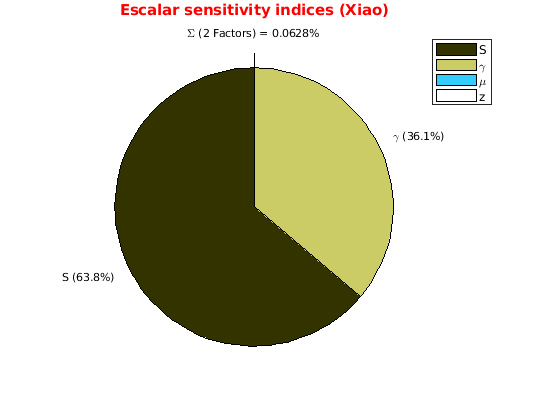

figure
gsua_plot('Pie',T_ia{3},T_ia{3}.STi)

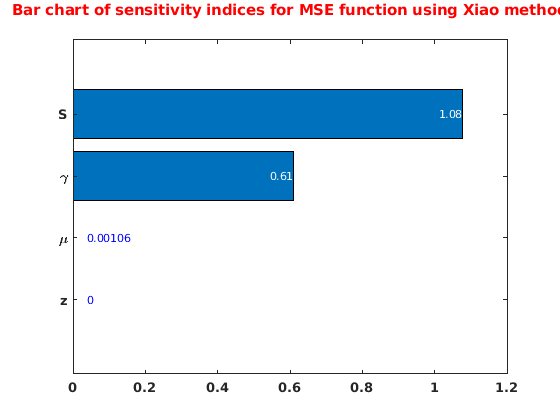

figure
gsua_plot('Bar',T_ia{3},T_ia{3}.STi)

Progress: 100%
Estimated processing time (h:m:s): 0:0:0
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:0:0
Estimated stop time (h:m:s): 19:2:2
Number of simulations: 1000


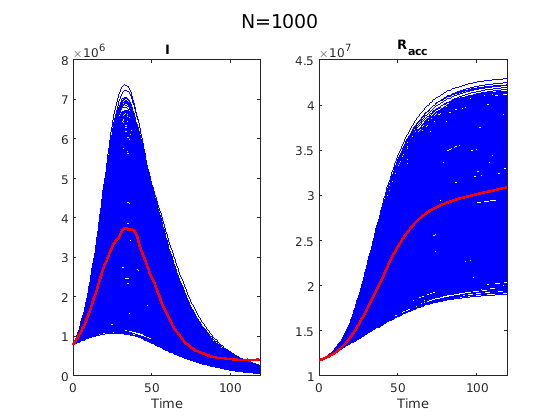

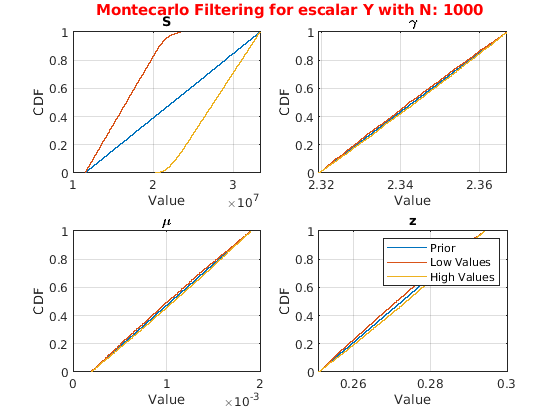

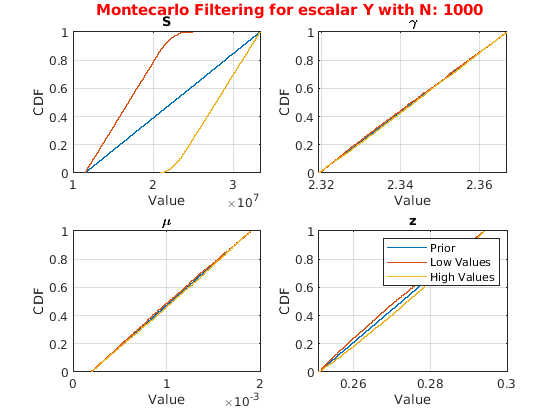

M = gsua_dmatrix(T_ia{2}, N, 'Method','Sobol');  
gsua_ua(M, T_ia{2},'xdata', xdata, 'ynom', ydata, 'parallel', false);